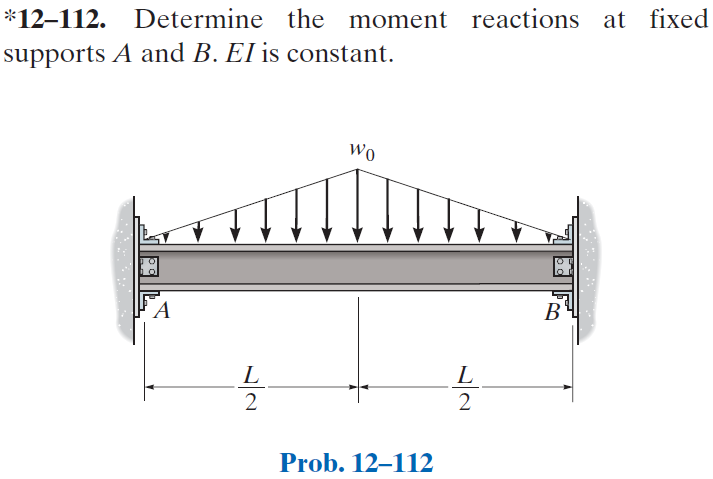

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-112P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-112P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

wo = sym('wo');
L = sym('L', 'positive');
w1 = findpoly(1, 'thru', [0 0], [L/2 -wo]);
w2 = findpoly(1, 'thru', [L/2 -wo], [L 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('reaction', 'force', 'Rb', L);
b = b.add('reaction', 'moment', 'Mb', L);
b = b.add('distributed', 'force', w1, [0 L/2]);
b = b.add('distributed', 'force', w2, [L/2 L], [false true]);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x^{2}\,\left(25\,L^{3}-40\,L^{2}\,x+16\,x^{3}\right)}{960\,\text{E}\,\text{I}\,L} & \text{ if }2\,x\leq L\\ -\frac{\mathrm{wo}\,{\left(L-x\right)}^{2}\,\left(L^{3}-8\,L^{2}\,x+48\,L\,x^{2}-16\,x^{3}\right)}{960\,\text{E}\,\text{I}\,L} & \text{ if }L<2\,x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,x\,\left(L-2\,x\right)\,\left(-5\,L^{2}+2\,L\,x+4\,x^{2}\right)}{96\,\text{E}\,\text{I}\,L} & \text{ if }2\,x\leq L\\ \frac{\mathrm{wo}\,\left(L-x\right)\,\left(L-2\,x\right)\,\left(L^{2}-10\,L\,x+4\,x^{2}\right)}{96\,\text{E}\,\text{I}\,L} & \text{ if }L<2\,x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,\left(5\,L^{3}-24\,L^{2}\,x+32\,x^{3}\right)}{96\,L} & \text{ if }2\,x\leq L\\ -\frac{\mathrm{wo}\,\left(13\,L^{3}-72\,L^{2}\,x+96\,L\,x^{2}-32\,x^{3}\right)}{96\,L} & \text{ if }L<2\,x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,\left(L-2\,x\right)\,\left(L+2\,x\right)}{4\,L} & \text{ if }2\,x\leq L\\ \frac{\mathrm{wo}\,\left(L-2\,x\right)\,\left(3\,L-2\,x\right)}{4\,L} & \text{ if }L<2\,x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{2\,\mathrm{wo}\,x}{L} & \text{ if }2\,x\leq L\\ -\frac{2\,\mathrm{wo}\,\left(L-x\right)}{L} & \text{ if }L<2\,x \end{array}\right.$$

# reactions and hinges

ra 

$$ra = \left(\begin{array}{cc} \mathrm{Ma} & \frac{5\,L^{2}\,\mathrm{wo}}{96}\\ \mathrm{Mb} & -\frac{5\,L^{2}\,\mathrm{wo}}{96}\\ \mathrm{Ra} & \frac{L\,\mathrm{wo}}{4}\\ \mathrm{Rb} & \frac{L\,\mathrm{wo}}{4} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

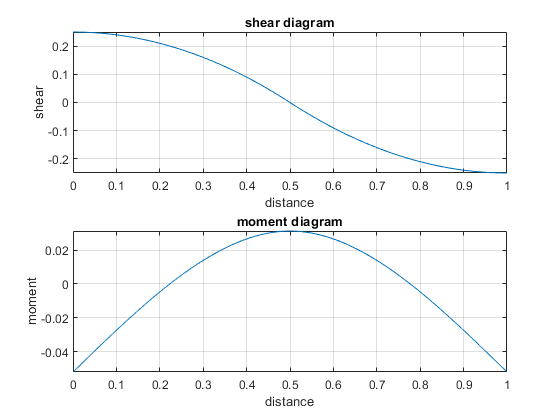

beam.shear_moment(m, v, [0 1], [wo L], 1);

# clean up

addvar(y);
new_assum = assumptions;